# Analysis of the Simulation Data from Double-Well Potential

clearvars;
addpath(genpath('../'))

## Generating simulation data

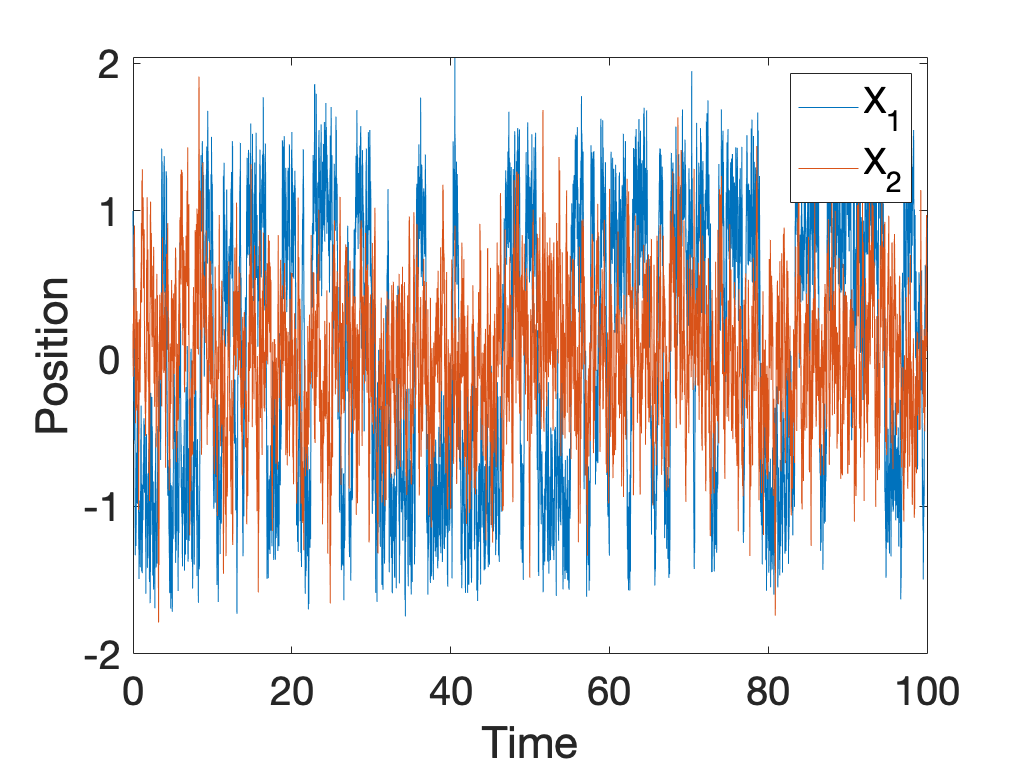

rng(1)
x_0 = [1,0]';
par.T_max = 100;
par.dt = 1e-2;
sigma = 2;
[x_out, t_out] = generating_simulation_data (@double_well_gradient_neg, sigma, x_0, par);
figure;
plot(t_out,x_out)
set(gca,'FontSize',20)
legend('X_{1}','X_{2}')
xlabel('Time')
ylabel('Position')

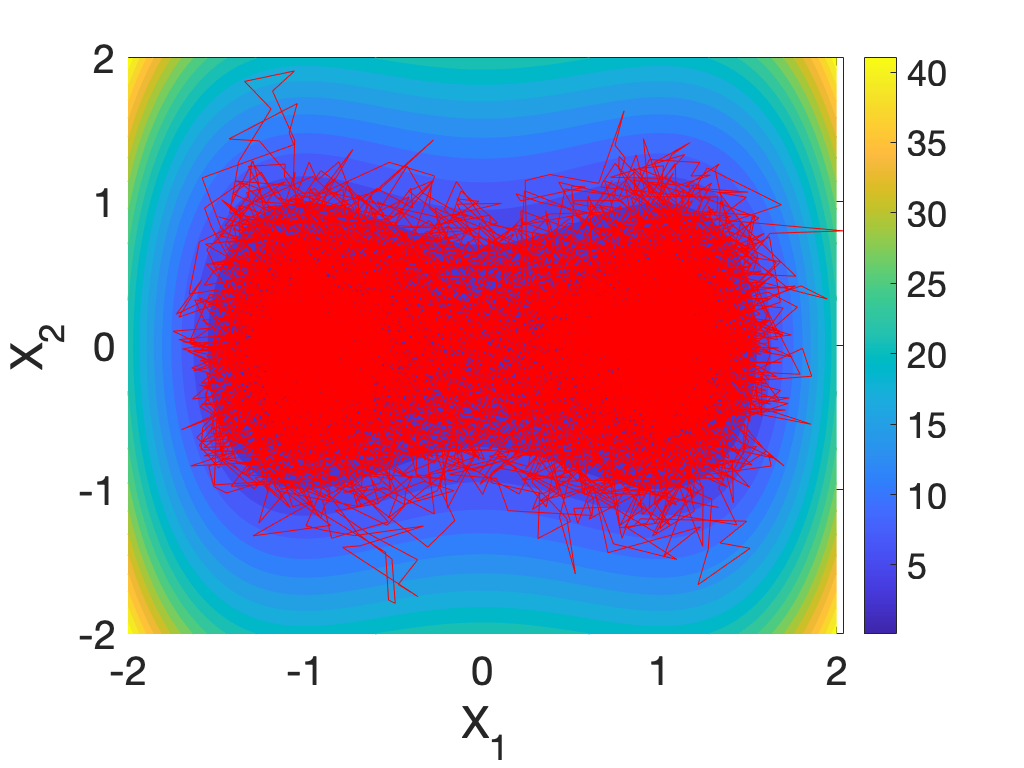

figure;
fc = fcontour(@double_well_potential,[-2 2 -2 2],'Fill',"on");
fc.LevelList = [-10:0.1:3,3:2:50];
set(gca,'FontSize',20)
colorbar
hold on
plot(x_out(1,:),x_out(2,:),"Color",'r','LineWidth',0.1)
xlabel('X_{1}')
ylabel('X_{2}')

data = x_out(:,1:5:end)';
%save 
%{
save('../Data/double_well.mat','x_out','t_out');
%}

## Load the Data and Estimate Number of Clusters by EPI

From EPI plot, we intend to seek for the index where peak occurs, which serves as the candidate for the choice of cluster numbers

out = EstClusterNum(data,[]);

Computed P-values 500 of 2001 datapoints...
Computed P-values 1000 of 2001 datapoints...
Computed P-values 1500 of 2001 datapoints...
Computed P-values 2000 of 2001 datapoints...
Mean value of sigma: 0.56525
Minimum value of sigma: 0.49359
Maximum value of sigma: 0.67268


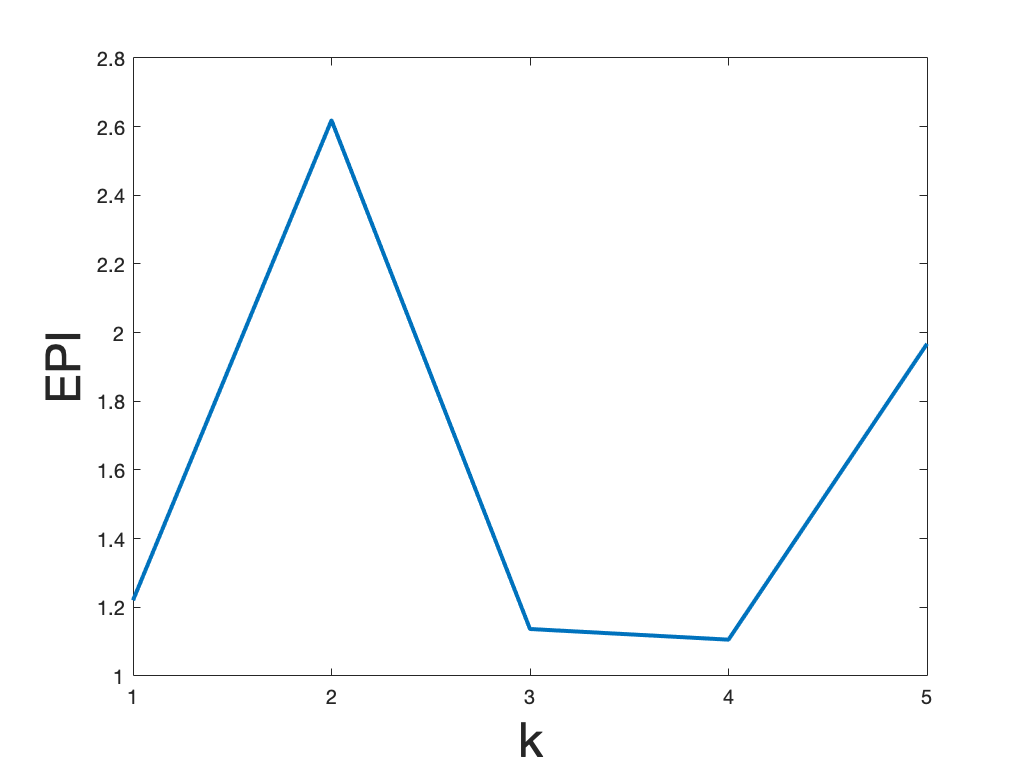

figure;
plot(out.ratio(1:5), 'linewidth',2.0)
xlabel('k', 'FontSize', 24);
ylabel('EPI', 'FontSize', 24);
xticks(0:30);

## Dynamical Analysis and Output

tic;
par.choice_distance = 'euclid';
par.K_cluster = 2; %selected based on EPI
par.trials = 2; % number of random trails in MuTrans, increase this to guaratee more robustness
% the main function of MuTrans
Output = DynamicalAnalysis (data, par);

Computed P-values 500 of 2001 datapoints...
Computed P-values 1000 of 2001 datapoints...
Computed P-values 1500 of 2001 datapoints...
Computed P-values 2000 of 2001 datapoints...
Mean value of sigma: 0.56525
Minimum value of sigma: 0.49359
Maximum value of sigma: 0.67268
Computed P-values 500 of 2001 datapoints...
Computed P-values 1000 of 2001 datapoints...
Computed P-values 1500 of 2001 datapoints...
Computed P-values 2000 of 2001 datapoints...
Mean value of sigma: 0.024841
Minimum value of sigma: 0.011406
Maximum value of sigma: 0.11343
Iteration 10: error is 49.7663
Iteration 20: error is 44.793
Iteration 30: error is 42.3252
Iteration 40: error is 41.6031
Iteration 50: error is 41.1513
Iteration 60: error is 40.9008
Iteration 70: error is 40.7205
Iteration 80: error is 40.5912
Iteration 90: error is 40.4917
Iteration 100: error is 1.8194
Iteration 110: error is 1.5155
Iteration 120: error is 1.2301
Iteration 130: error is 1.0449
Iteration 140: error is 0.92788
Iteration 150: error

J_new = 1.8448

J_new = 1.8440

J_new = 1.8435

J_new = 1.8432

J_new = 1.8431

J_new = 1.8430

J_new = 1.8430

Computed P-values 500 of 2001 datapoints...
Computed P-values 1000 of 2001 datapoints...
Computed P-values 1500 of 2001 datapoints...
Computed P-values 2000 of 2001 datapoints...
Mean value of sigma: 0.024841
Minimum value of sigma: 0.011406
Maximum value of sigma: 0.11343
Iteration 10: error is 49.7659
Iteration 20: error is 44.7401
Iteration 30: error is 42.4186
Iteration 40: error is 41.805
Iteration 50: error is 41.4433
Iteration 60: error is 41.0955
Iteration 70: error is 40.8841
Iteration 80: error is 40.7423
Iteration 90: error is 40.629
Iteration 100: error is 1.8534
Iteration 110: error is 1.5425
Iteration 120: error is 1.2628
Iteration 130: error is 1.0745
Iteration 140: error is 0.95517
Iteration 150: error is 0.88338
Iteration 160: error is 0.83358
Iteration 170: error is 0.79519
Iteration 180: error is 0.76592
Iteration 190: error is 0.74267
Iteration 200: error is 0.72378
Iteration 210: error is 0.70833
Iteration 220: error is 0.69542
Iteration 230: error is 0.6845
Iterat

J_new = 1.8440

J_new = 1.8432

J_new = 1.8431

J_new = 1.8430

J_new = 1.8430

E_best = 0.1465

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          1.84352                      1.94e-05
     1          11          1.79746         158511       0.000297  
     2          14           1.7973      0.0231234       0.000316  
     3          15          1.79128              1       0.000133  
     4          16          1.78939              1       0.000184  
     5          17          1.78791              1       9.97e-05  
     6          18          1.78707              1       5.03e-05  
     7          19          1.78657              1       9.08e-05  
     8          20          1.78628              1       7.29e-05  
     9          21           1.7859              1       2.43e-05  
    10          22          1.78563              1       2.96e-05  
    11          23          1.78544              1       3.21e-05  
    12          24          1.78529              

toc;

Elapsed time is 38.340527 seconds.



class_order = Output.class_order;
rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_perm = Output.P_perm;
P_hat = Output.P_hat;
P_appr_perm = Output.P_appr_perm;
P_rho = Output.P_rho;
labs_perm = Output.labs_perm;
data_perm = Output.data_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;

Plot the Cell-Cell Scale rwTPM

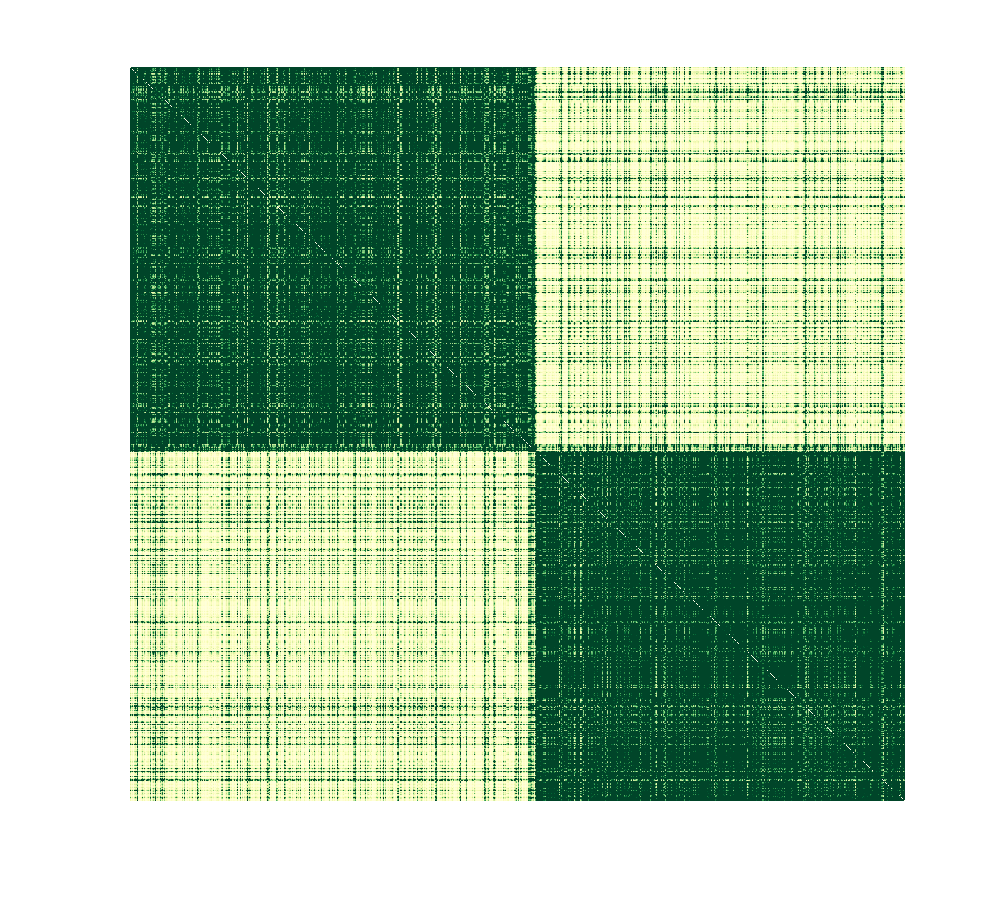

max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

%colorbar;

Plot the Cluster-Cluster Scale rwTPM

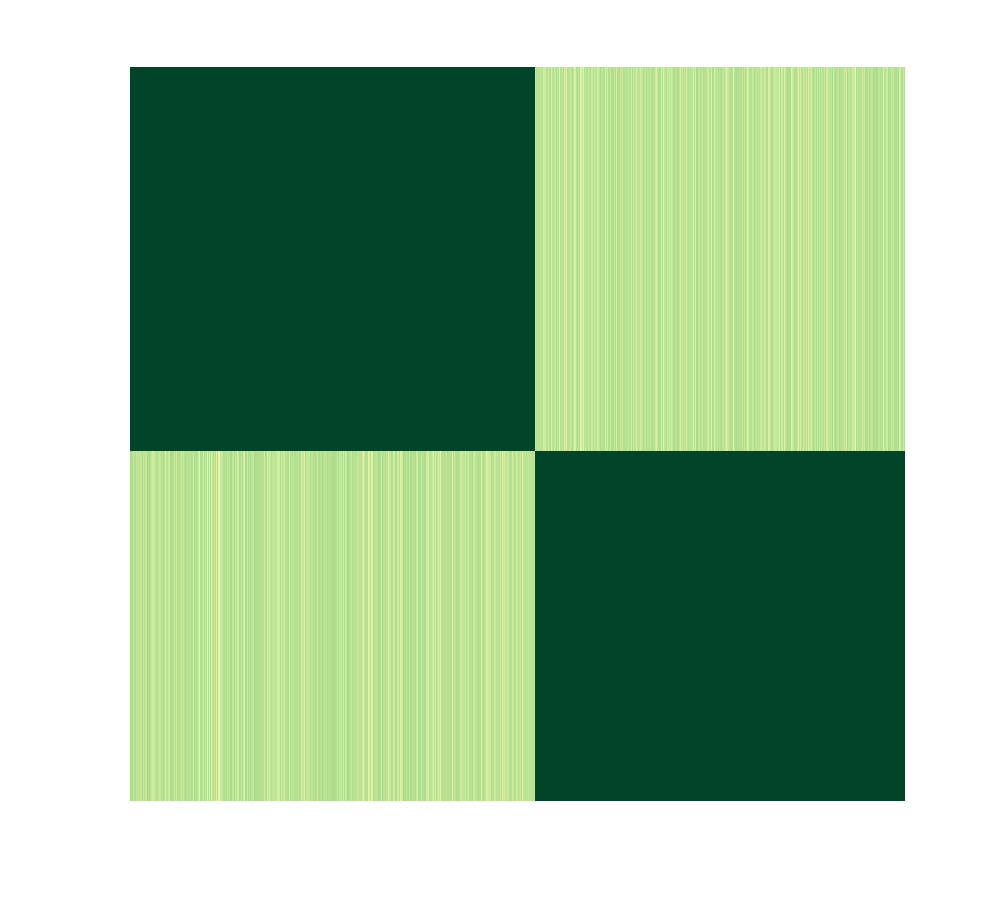

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

%colorbar;


Plot the Cell-Cluster Scale rwTPM

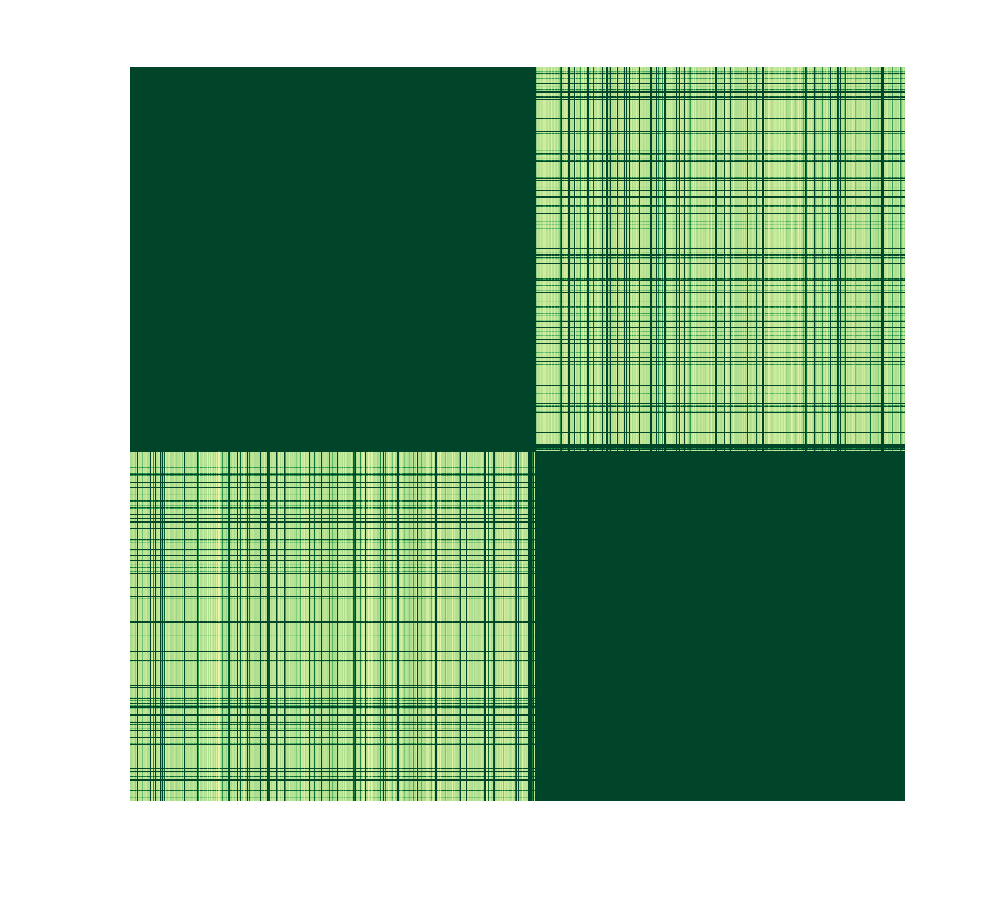


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off

Plot Transition Cell Score (TCS)

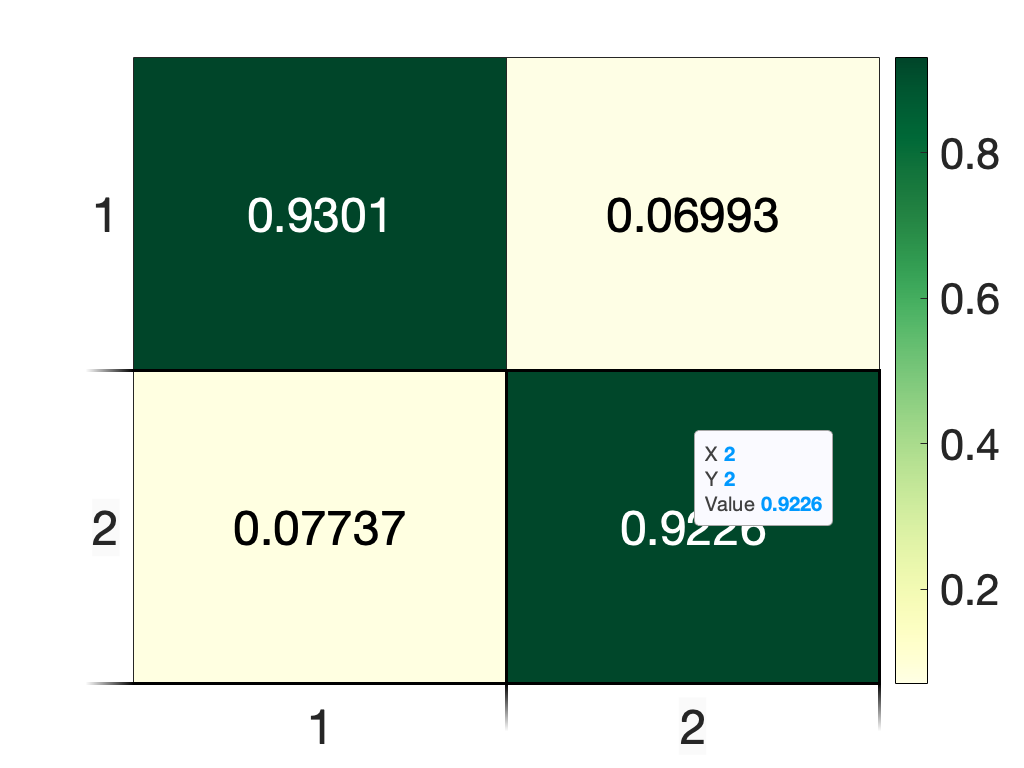

figure
heatmap(P_hat,'Colormap',colormap(brewermap([],cmp)),'FontSize',24)

figure

P_hat =     0.9301    0.0699
    0.0774    0.9226


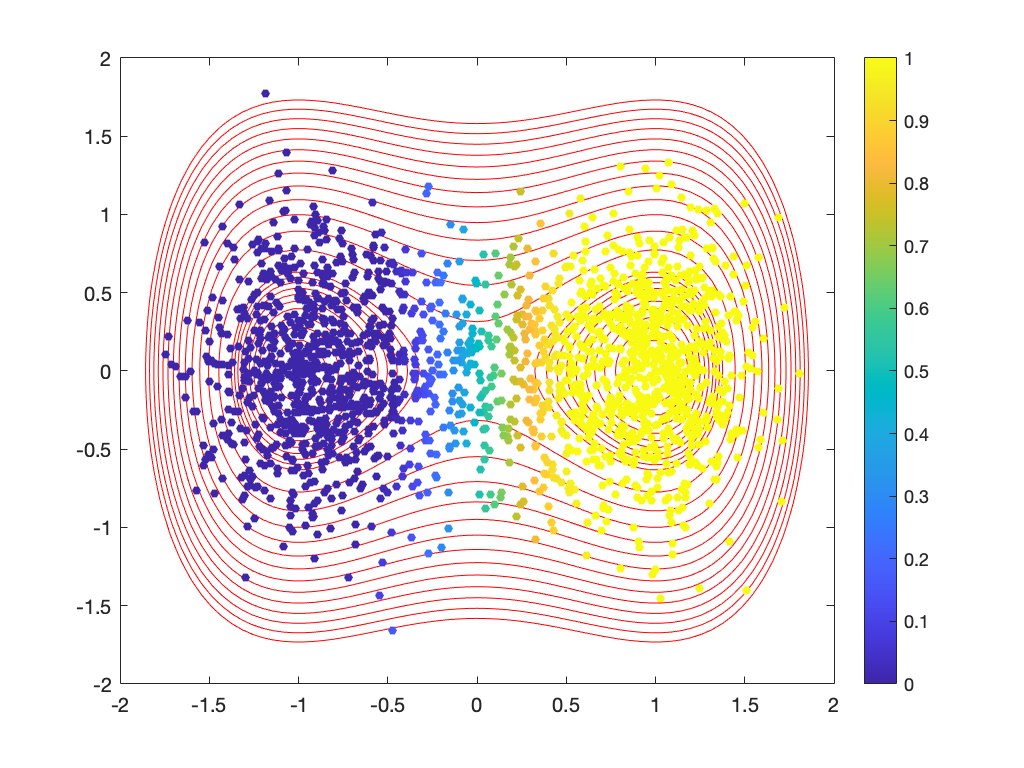

fc = fcontour(@double_well_potential,[-2 2 -2 2],'-r');
fc.LevelList = [0:0.2:2,3:15];
hold on
scatter(data_perm(:,1),data_perm(:,2),20,rho_class(:,1),'filled') 
colorbar 
caxis([0 1])

set(gca,'FontSize',20)
xlabel('X_{1}')
ylabel('X_{2}')

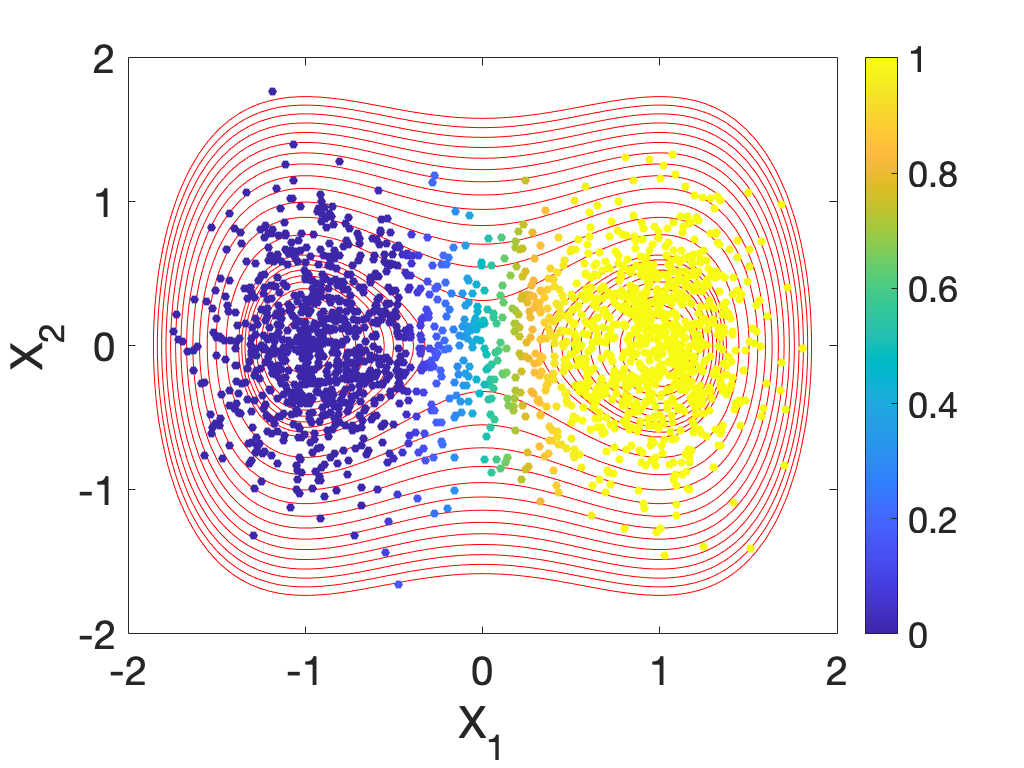

figure
fc = fcontour(@double_well_potential,[-2 2 -2 2],'-r');
fc.LevelList = [0:0.2:2,3:15];
hold on
scatter(data_perm(:,1),data_perm(:,2),20,rho_class(:,1),'filled') 
colorbar 
caxis([0 1])
set(gca,'FontSize',20)
xlabel('X_{1}')
ylabel('X_{2}')

function v = double_well_potential(x,y)
    v = 2.5*(x.^2-1).^2+5*y.^2;
end

function dv = double_well_gradient_neg(x)
    dv = zeros(2,1);
    dv(1) = -10*(x(1)^2-1)*x(1);
    dv(2) = -10*x(2);
end